# PH-STAT: Statistical Inference on Persistent Homology

% The package performs statitical inference on persistent homology
% The package can be downloaded from
% https://github.com/laplcebeltrami/PH-STAT
% If you are using the package, reference 
% Chung 2025. PH-STAT, arXiv:2304.05912
%
% (C) 2023 Moo K. Chung
% Universtiy of Wisconsin-Madison 
%
% email: mkchung@wisc.edu
%
% Update history: 
%   2023 Sept 11 created
%   2025 Feb 20 Function for drawing simplical complex corresponding to
%               given boundary matrices are added.
%   2025 Mar 3  Higher order connectivity added, 
%               Wasserstein distance error fixed


## Morse filtration

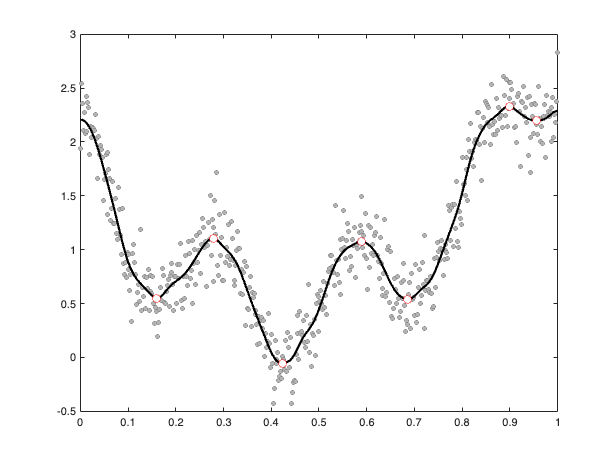

%The construction for the persistence diagrm for 1D function is based on the 
%iterative pairing and deleation algorithm in
% 
% Chung, M.K., Singh, V., Kim, P.T., Dalton, K.M., Davidson, R.J. 2009. 
% Topological characterization of signal in brain images using the min-max diagram. 
% 12th International Conference on Medical Image Computing and Computer Assisted 
% Intervention (MICCAI). Lecture Notes in Computer Science (LNCS). 5762:158-166.

%Toy example
% In the interval x=[0, 1], we construct a signal s and add noise e to obtain simulated signal Y.
x=[0:0.002:1]';  %interval
s= x + 7*(x - 0.5).^2 + cos(7*pi*x)/2; %signal
e=normrnd(0,0.2,length(x),1); %noise
Y=s+e; %observed data = signal + noise

figure;
plot(x,Y,'ko','MarkerEdgeColor',[0.5 0.5 0.5], 'MarkerFaceColor',[0.7 0.7 0.7], 'MarkerSize',4)

%This produces a scatter points so we can't obtain critical values directly. 
% We smooth out the scatter plot using heat kernel smoothing with bandwidth 0.0001 
% and cosine series expansion upto degree 100. The resulting smoothed signal is stored in the variable wfs.

k=100; sigma=0.0001;
[wfs, beta]=WFS_COS(Y,x,k,sigma);

hold on;
plot(x,wfs,'k','LineWidth',2);

%Then using the iterative pairing and deleation algorithm pairing_1D, we determine 
% the pairing of minimums and maximums using the Elder's rule.  
% pairing_1D.m plots critical values as white notes.

pairs=PH_morse1D(x,wfs);

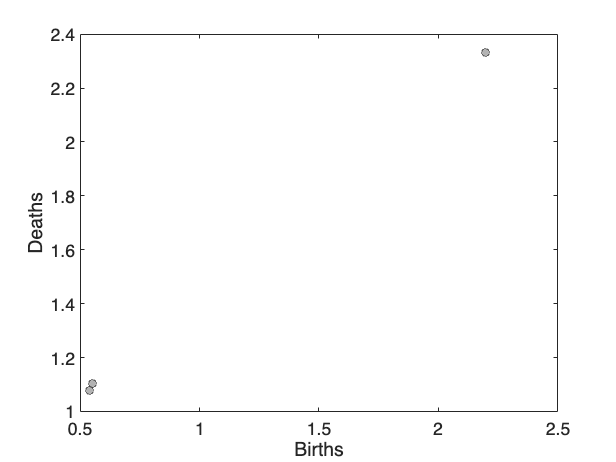

PH_PD_display(pairs)

## Rips complex

%genrate random p number of scatter points in [0,1]^d hyper-cube.
%X is the matrix of size p x d of coordinates
rng(2023); %fixed random seeds
p=50; d=3;
X = rand(p, d);

%Compute the Rips complex up to 3-simplices.
%The first column contains information about simplical complexes. 
%The second column contains data over nodes, edges, faces, volumes, etc.

radius = 0.3;
S= PH_rips(X, 3, radius)

S = 4×2 cell array
    { 50×1 double}    { 50×1 double}
    {101×2 double}    {101×1 double}
    { 73×3 double}    { 73×1 double}
    { 27×4 double}    { 27×1 double}


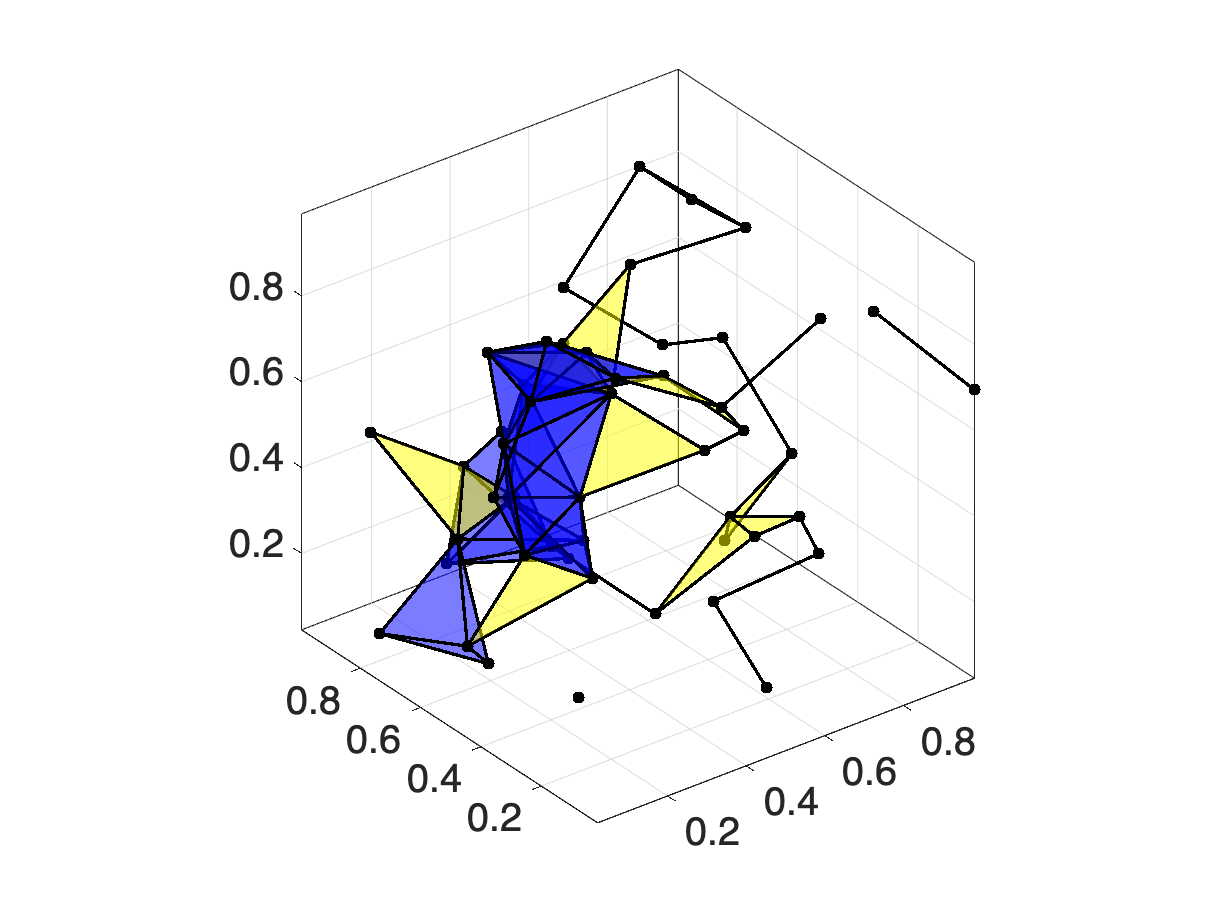

%The first column contains simplicial complex information
%The second column contains functional data information

%Display Ris complex
PH_rips_display(X,S);

%Yellow: 2-simplices, blue: 3-simplices 

%Below lines will display nodes indexing
%labels = cellstr(num2str((1:p)', '% d'));
%text(X(:,1)+0.01, X(:,2)+0.01, X(:,3)+0.01, labels, 'Color', 'r', 'FontSize',14) 

## Boundary matrices


% From given simplical complex S, we will build boundary matrices
B = PH_boundary(S)

B = 3×1 cell array
    { 50×101 double}
    {101×73  double}
    { 73×27  double}


betti = PH_boundary_betti(B)

betti =      3     4     0


## Higher order connectivity

%Although there are a lot of talks on higher order interaction or
%connectivity in particuarly brain netowrks in literature, they are not obervable
%consisetntly mainly due to the use of correlation networks, which
%produce dense networks.

%genrate random p number of scatter points in [0,1]^d hyper-cube.
%X is the matrix of size p x d of coordinates
rng(2023); %fixed random seeds
p=50; 
p=50; d=3;
X = rand(p, d); %coordinates
C = randcorr(p); %connectivity

tau=0.2;
maxDim=3;
S = PH_connectivity2simplex(C, tau, maxDim)

S = 1×4 cell array
    {50×1 double}    {102×2 double}    {18×3 double}    {[13 18 32 40]}


B = PH_boundary(S)

B = 3×1 cell array
    { 50×102 double}
    {102×18  double}
    { 18×1   double}


betti = PH_boundary_betti(B)

betti =      1    36     0


% β₀ counts connected components.
% β₁ counts independent cycles (loops) that are not the boundary of any 2-simplex.
% β₂ counts 2-dimensional voids (or cavities).



## Graph filtrations

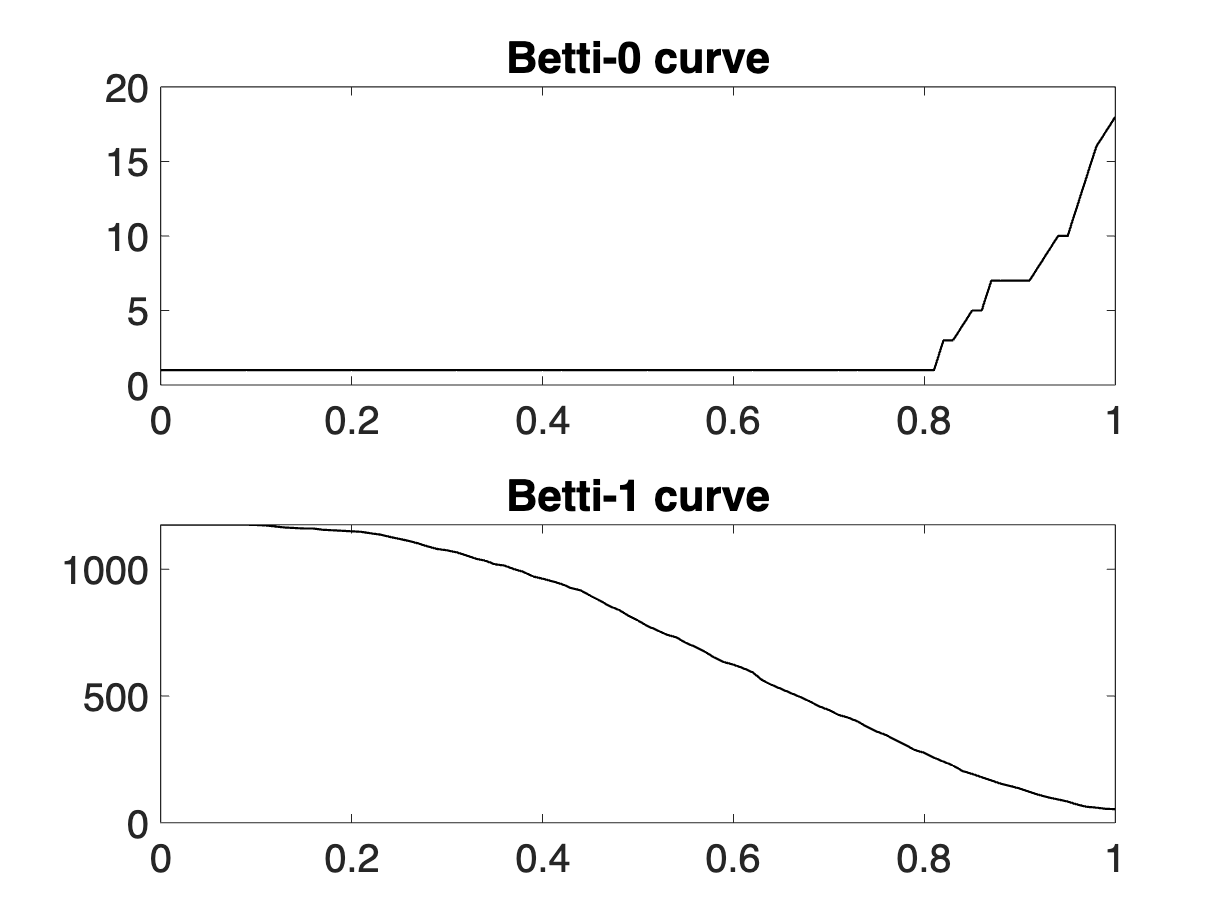


% The graph filtration is explained in 
%
% Chung, M.K., Lee, H. Ombao. H., Solo, V. 2019 Exact topological inference 
% of the resting-state brain networks in twins, Network Neuroscience 3:674-694
% http://www.stat.wisc.edu/~mchung/papers/chung.2019.NN.pdf
%
% Chung, M.K., Huang, S.-G., Gritsenko, A., Shen, L., Lee, H. 2o19
% Statistical inference on the number of cycles in brain networks. 
% IEEE International Symposium on Biomedical Imaging (ISBI) 113-116
%
% The graph filtration over filtration values epsilon is matheamticall equivaelnt 
% to the Rips filtration with filtration values maximum distance - epsilon up to 1-simplices only.  

%This will generate the identical scatter points 
% as Rips filtration example
rng(2023); %fixed random seeds
p=50; d=3;
X = rand(p, d); 

C = pdist2(X,X); %edge weights
maxw = 1; %max(w(:)); %maximum edge weight


%Betti curves over graph filtration
thresholds=[0:0.01:maxw]; %filtration values
beta = PH_betti(C, thresholds);

%display betti curves (beta-0 and beta-1)
PH_betti_display(beta,thresholds)

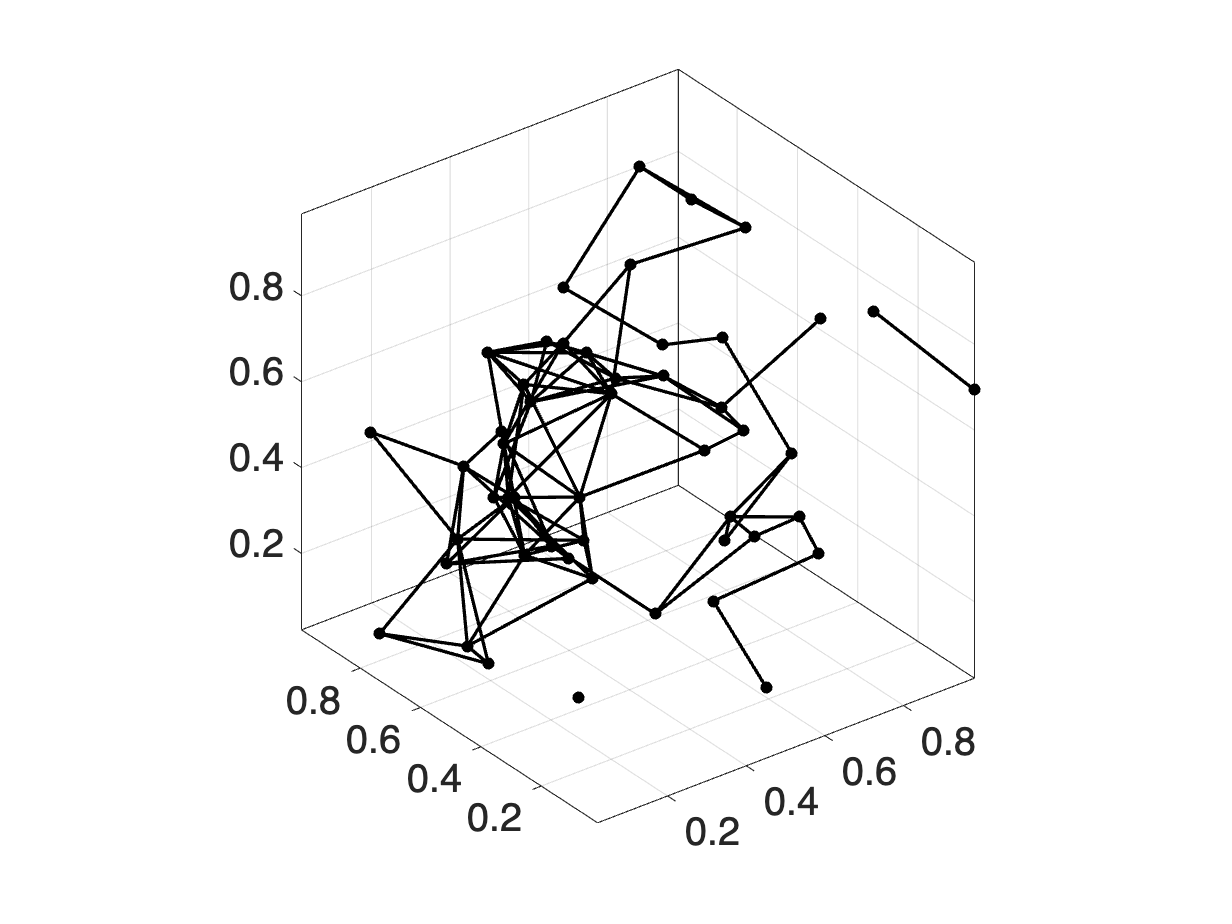


%Equvalently, we can compute the graph filtration as the 
%reverse Rips filtraions restricted to 1-skeleton. 
%The graph filtration at filtraion value e is equivalent to
e = 0.7;
S= PH_rips(X, 1, maxw-e);
PH_rips_display(X,S); 

## Topoloigcal inference on the Wasserstein distance

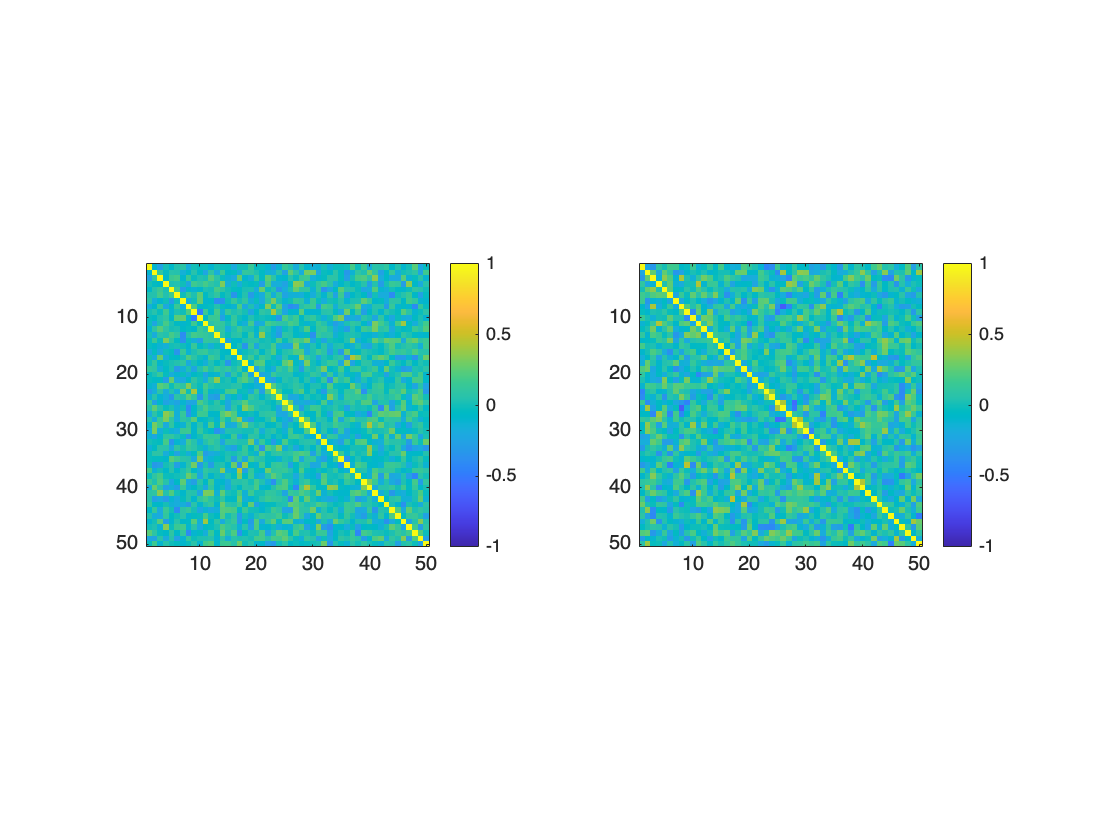

% The Wasserstein distance in graph filtration is simplied to 1D
% Wasserstein distance, which has the exact solution and can be computed in
% O(p log q) run time. The deail is given in 

% Songdechakraiwut, T., Shen, L., Chung, M.K. 2021 Topological learning and 
% its application to multimodal brain network integration, Medical Image 
% Computing and Computer Assisted Intervention (MICCAI), LNCS 12902:166-176 
%
% Songdechakraiwut, T. Chung, M.K. 2023 Topological learning for brain networks, 
% Annals of Applied Statistics 17:403-433, arXiv:2012.00675.
% https://arxiv.org/pdf/2012.00675.pdf


% Random correlation matrix simulations

p=50; %# of nodes

% i-th group has less noise
rng(1); 
nGroup_i=5; %5 subjects 
signal_i = randcorr(p); %this serves as the ground truth signal
for i=1:nGroup_i
    con_i(:,:,i) = signal_i + randcorr(p); %signal plus noise
end

%j-th group has twice more noise
rng(2);
nGroup_j=5; %5 subject 
signal_j = signal_i;
for j=1:nGroup_j 
    con_j(:,:,j) = signal_j + 2*randcorr(p); %signal plus noise
end

figure; subplot(1,2,1); imagesc(mean(con_i,3))
axis square; clim([-1 1]); colorbar;
subplot(1,2,2); imagesc(mean(con_j,3))
axis square; clim([-1 1]); colorbar

% Computing and visualizing Betti-0 and Betti-1 curves

thresholds=[-0.5:0.01:1]; %you can change the range
PH_graph_betti_display(con_i, con_j,thresholds)

% Pairwise topological distance map. It includes 3 topological distances

lossMtx = WS_pdist2(con_i,con_j);
WS_pdist2_display(con_i,con_j);


% p-value computation using the raio statistic (between-distance/within-distance)
%Here we show example of using the combined distance. For different
%distances,use lossMtx.D0 or lossMtx.D1, lossMtx.D01 = lossMtx.D0 + lossMtx.D1.

observed = WS_ratio(lossMtx.D01, nGroup_i, nGroup_j) 

observed = 60.2090

nTrans = 1000000; %Total number of transpositions
permNo = 1000; %Total number of intermixed permutations. This is needed to introduce randomness.

[transStat, ~] = WS_transpositions(lossMtx.D01, nGroup_i, nGroup_j, nTrans, permNo); 
transPval = online_pvalues(transStat', observed);
pval = transPval(end)

pval = 0.0011

figure; plot(transPval(1:100000)); ylim([0 0.05])


% histrogram. red line is observed statistic
figure; %hisgrom with 25 bins
plot_distribution(transStat, 25, observed)

## Distribution of Wasserstein distance

% We determine the empirical probability distribution of the Wasserstein
% distances 


% Songdechakraiwut, T., Shen, L., Chung, M.K. 2021 Topological learning and 
% its application to multimodal brain network integration, Medical Image 
% Computing and Computer Assisted Intervention (MICCAI), LNCS 12902:166-176 
%
% Songdechakraiwut, T. Chung, M.K. 2023 Topological learning for brain networks, 
% Annals of Applied Statistics 17:403-433, arXiv:2012.00675.
% https://arxiv.org/pdf/2012.00675.pdf


% Random correlation matrix simulations

p=50; %# of nodes

% i-th group has less noise
rng(1); 
nGroup_i=5; %# of subjects 
for i=1:nGroup_i
    con_i(:,:,i) = randcorr(p); %signal plus noise
end

%j-th group should not be different from i-th group
rng(2);
nGroup_j=5; %# of subject 
for j=1:nGroup_j 
    con_j(:,:,j) = randcorr(p); %signal plus noise
end


lossMtx = WS_pdist2(con_i,con_j);

D0_vector = lossMtx.D0(triu(true(size(lossMtx.D0)), 1));
D1_vector = lossMtx.D1(triu(true(size(lossMtx.D1)), 1));

figure;
subplot(1, 2, 1);
plot_distribution(D0_vector,50,[])
%histogram(D0_vector, 'Normalization', 'probability');
title('Distribution of D_{W0}');
xlabel('Distance');
ylabel('Probability');

subplot(1, 2, 2);
plot_distribution(D1_vector,50,[])
title('Distribution of D_{W1}');
xlabel('Distance');
ylabel('Probability');
print_pdf('dist_equal')

## Topological clustering using the Wasserstein distance

% The Wasserstin distance based topological clustering is explained in
%
% Chung, M.K.,  Ramos, C.G., De Paiva, F.B., Jedidiah M., Prabharakaren, V., Nair, V.A., 
% Meyerand, E., Hermann, B.P., Binder, J.R., Struck, A.F. 2023 arXiv preprint arXiv:2302.06673
% https://arxiv.org/pdf/2302.06673

g_i = squeeze(mat2cell(con_i, p, p, ones(nGroup_i,1))); %convert to cell array
g_j = squeeze(mat2cell(con_j, p, p, ones(nGroup_j,1))); %convert to cell array
G=[g_i g_j];

%Topological clustering
acc_WS  = WS_cluster(G)

acc_WS = struct with fields:
    mean: 1
     std: 0



%k-means clustering
acc_K = kmeans_cluster(G)

acc_K = struct with fields:
    mean: 0.5820
     std: 0.0796


% Hierarchical clustering based on the Gromov-Hausdorff (GH) distance.
% The clusetering method was published in 
%
% Lee, H., Chung, M.K., Kang, H., Kim, B.-N., Lee, D.S. 2011. Computing the shape of brain network 
% using graph filtration and Gromov-Haudorff metric. 14th International Conference on Medical Image 
% Computing and Computer Assisted Intervention (MICCAI). Lecture Notes in Computer Science (LNCS). 6892:302-309.

acc_H = GH_cluster(G)

acc_H = 0.6000

## Topololigcal embedding

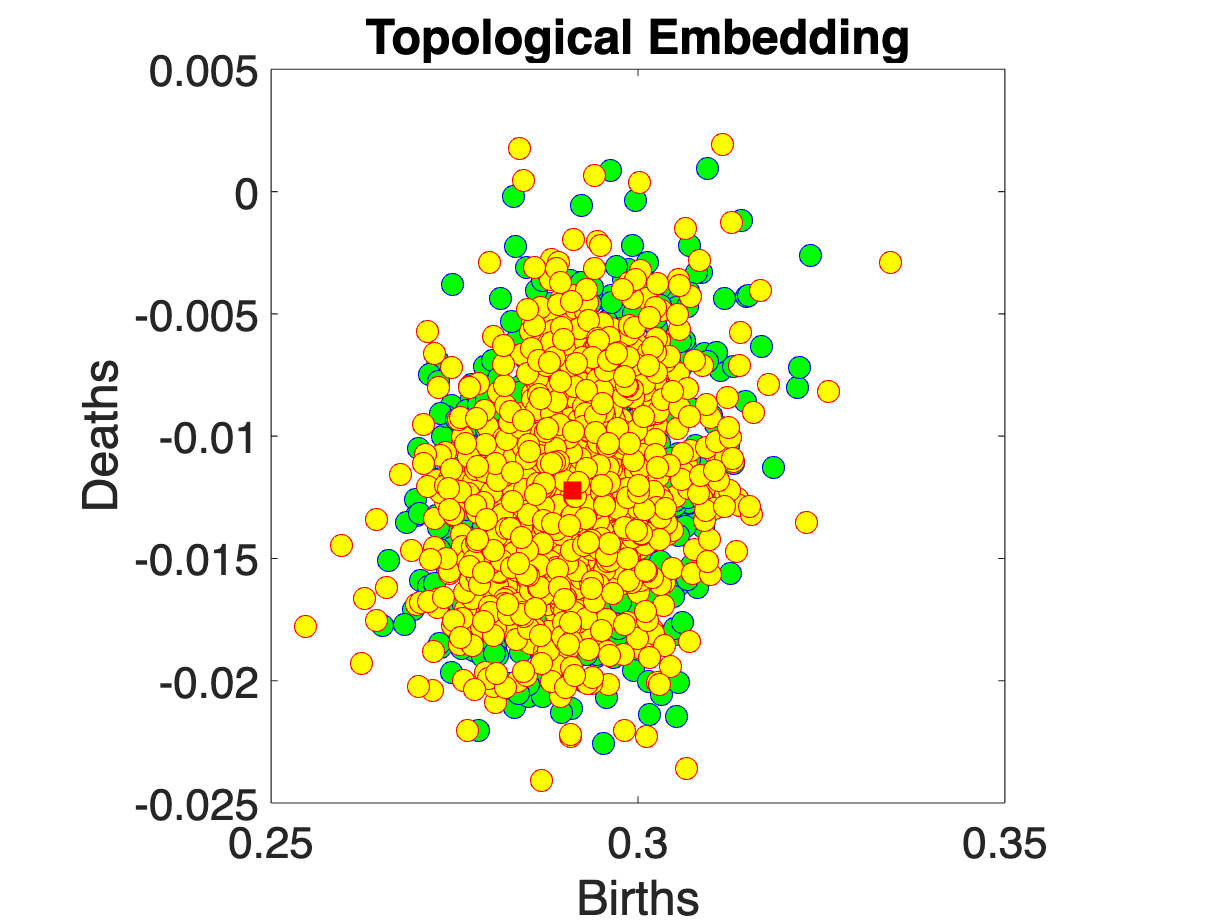

% The topological embedding is explained in
% Moo K. Chung, Camille Garcia Ramos, Felipe Branco De Paiva, Jedidiah Mathis, Vivek Prabharakaren, 
% Veena A. Nair, Elizabeth Meyerand, Bruce P. Hermann, Jeffery R. Binder, Aaron F. Struck, 2023 
% Unified Topological Inference for Brain Networks in Temporal Lobe Epilepsy Using the Wasserstein 
% Distance, arXiv:2302.06673.
%
% The simulation setting comes from
% Chung, M.K., Huang, S.-G., Carroll, I.C., Calhoun, V.D., Goldsmith, H.H. 
% 2023 Topological  State-Space Estimation of Functional Human Brain Networks. arXiv:2201:00087

[z_i, c_i] = WS_embed(con_i);
[z_j, c_j] = WS_embed(con_j);

figure;
plot(z_i(:,1) +c_i(1), z_i(:,2) + c_i(2), 'ob', 'MarkerSize',10, 'MarkerFaceColor','g')
hold on; plot(c_i(1), c_i(2), 'sb', 'MarkerSize',10, 'MarkerFaceColor','b')

hold on; plot(z_j(:,1) +c_j(1), z_j(:,2) + c_j(2), 'or','MarkerSize',10, 'MarkerFaceColor','y')
hold on; plot(c_j(1), c_j(2), 'sr', 'MarkerSize',10, 'MarkerFaceColor','r')
axis square
xlabel('Births');
ylabel('Deaths')
title('Topological Embedding')
figure_bigger(20)